## [Temperature Control of a Stirred Reactor](https://apmonitor.com/pdc/index.php/Main/StirredReactor)

The objective of this case study is to automatically maintain a temperature in stirred tank reactor with a highly exothermic reaction. This is an example of a highly nonlinear process that is prone to exponential run-away when the temperature rises too quickly.

A reactor is used to convert a hazardous chemical *A* to an acceptable chemical *B* in waste stream before entering a nearby lake. This particular reactor is dynamically modeled as a Continuously Stirred Tank Reactor (CSTR) with a simplified kinetic mechanism that describes the conversion of reactant *A* to product *B* with an irreversible and exothermic reaction. Because the analyzer for product *B* is not fast enough for real-time control, it is desired to maintain the temperature at a constant set point that maximizes the consumption of *A* (highest possible temperature).

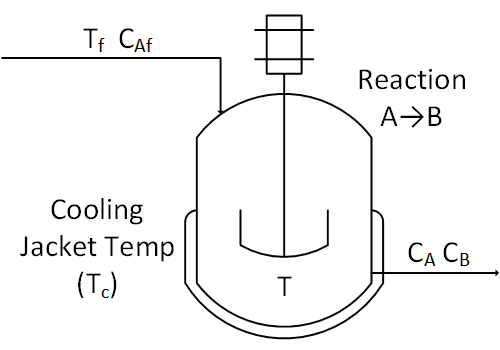

The exercise involves creating a dynamic first-order model, obtaining tuning parameters, and adjusting the PID tuning to achieve acceptable performance.

## Doublet Test for FOPDT Fit

viewSolution(false)

Perform the necessary open loop tests to determine a first order plus dead time (FOPDT) model that describes the relationship between cooling jacket temperature (MV=*T**c*) and reactor temperature (CV=*T*). Use the file data.txt to extract the information for the FOPDT model. Obtain an FOPDT model and report the values of the three parameters $K_p,\tau_p,\theta_p$.

Below is a step test example in Python. Modify this to start at 300K for the cooling jacket temperature, step up to 303K, down to 297K, and back to 300K in a doublet test. Fit $K_p,\tau_p,\theta_p$ of an FOPDT model **using optimization** to achieve the best match to the simulated CSTR data.

**The functions cstr, fopdt, sim_model, and objective will likely help.**

## Design PI or PID Controller

viewSolution2(false)

Use the $K_p,\tau_p,\theta_p$ from the FOPDT model in the [**Internal Model Control (IMC) PI tuning correlation**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralControl) or [**PID tuning correlation**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative) to obtain starting values of $K_c,\tau_I$ and $\tau_D$ for a PI or PID controller. Use an aggressive value for the closed loop time constant, $\tau_c=0.1\tau_p$.

## Implement PI or PID Controller

viewSolution3(false)

Using $K_c,\tau_I$ and $\tau_D$ from the IMC tuning correlation, implement a PID controller with anti-reset windup. Test the set point tracking capability of this controller by plotting the response of the process to steps in set point of the reactor temperature (not cooling jacket temperature) from 300K up to 320K and then down to 280K. Limit the cooling jacket temperature between 250K and 350K. Comment on how the nonlinear behavior of this process impacts your observed set point response performance.

## Tune PI or PID Controller

viewSolution4(false)

Improve the tuning by adjusting $K_c,\tau_I$ and $\tau_D$ by trial and error until the controller displays a 10% to 15% overshoot in response to a reactor temperature set point step from 300K to 320K. Plot this set point step response.

## Challenge: Lowest Concentration

Step up the set point to achieve a maximum temperature in the reactor without exceeding the maximum allowable temperature of 400K (don’t cause a reactor run-away). What is the lowest concentration that can be achieved without exceeding the maximum allowable temperature? This is a very difficult problem due to the potential for reactor temperature run-away. **Derivative action** may be necessary to achieve the best performance.

## CSTR Model

function xdot = cstr(~,x,u,Tf,Caf)
    % Inputs (3):
    % Temperature of cooling jacket (K)
    Tc = u;
    % Tf = Feed Temperature (K)
    % Caf = Feed Concentration (mol/m^3)

    % States (2):
    % Concentration of A in CSTR (mol/m^3)
    Ca = x(1);
    % Temperature in CSTR (K)
    T = x(2);

    % Parameters:
    % Volumetric Flowrate (m^3/sec)
    q = 100;
    % Volume of CSTR (m^3)
    V = 100;
    % Density of A-B Mixture (kg/m^3)
    rho = 1000;
    % Heat capacity of A-B Mixture (J/kg-K)
    Cp = 0.239;
    % Heat of reaction for A->B (J/mol)
    mdelH = 5e4;
    % E - Activation energy in the Arrhenius Equation (J/mol)
    % R - Universal Gas Constant = 8.31451 J/mol-K
    EoverR = 8750;
    % Pre-exponential factor (1/sec)
    k0 = 7.2e10;
    % U - Overall Heat Transfer Coefficient (W/m^2-K)
    % A - Area - this value is specific for the U calculation (m^2)
    UA = 5e4;
    % reaction rate
    rA = k0*exp(-EoverR/T)*Ca;

    % Calculate concentration derivative
    dCadt = q/V*(Caf - Ca) - rA;
    % Calculate temperature derivative
    dTdt = q/V*(Tf - T) + mdelH/(rho*Cp)*rA + UA/V/rho/Cp*(Tc-T);
    
    % Return xdot:
    xdot = zeros(2,1);
    xdot(1) = dCadt;
    xdot(2) = dTdt;
end

## FOPDT Model

function dydt = fopdt(t,y,uf,Km,taum,thetam,yp0,u0)
    % arguments
    %  y      = output
    %  t      = time
    %  uf     = input linear function (for time shift)
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model time constant
    % time-shift u
    try
        if (t-thetam) <= 0
            um = uf(0.0);
        else
            um = uf(t-thetam);
        end        
    catch
        um = u0;
    end
    % calculate derivative
    dydt = (-(y-yp0) + Km * (um-u0))/taum;
end

## Simulate FOPDT Model with x= $K_m,\tau_m,\theta_m$

function ym = sim_model(x,ns,yp0,dt,u_fit,u0)
    % input arguments
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    % storage for model values
    ym = zeros(ns,1);  % model
    % initial condition
    ym(1) = yp0;
    % loop through time steps    
    for i=1:ns-1
        ts = [dt*i,dt*(i+1)];
        %fopdt(t,y,uf,Km,taum,thetam)
        [~,y1] = ode45(@(t,y) fopdt(t,y,u_fit,Km,taum,thetam,yp0,u0),ts,ym(i));
        ym(i+1) = y1(end);
    end
end

## Define Objective

function obj = objective(x,ns,yp0,dt,u_fit,u0,yp)
    % simulate model
    ym = sim_model(x,ns,yp0,dt,u_fit,u0);
    % calculate objective
    obj = 0.0;
    for i=1:length(ym)
        obj = obj + (ym(i)-yp(i))^2;    
    end
end

## Solutions

function viewSolution(view)
if view
	disp("% Steady State Initial Conditions for the States" + newline + ...
	     "Ca_ss = 0.87725294608097;" + newline + ...
	     "T_ss = 324.475443431599;" + newline + ...
	     "x0 = zeros(2,1);" + newline + ...
	     "x0(1) = Ca_ss;" + newline + ...
	     "x0(2) = T_ss;" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Condition" + newline + ...
	     "u_ss = 300.0;" + newline + ...
	     "% Feed Temperature (K)" + newline + ...
	     "Tf = 350;" + newline + ...
	     "% Feed Concentration (mol/m^3)" + newline + ...
	     "Caf = 1;" + newline + ...
	     "" + newline + ...
	     "% Time Interval (min)" + newline + ...
	     "t = linspace(0,25, 251);" + newline + ...
	     "" + newline + ...
	     "% Store results for plotting" + newline + ...
	     "Ca = ones(1,length(t)) * Ca_ss;" + newline + ...
	     "T = ones(1,length(t)) * T_ss;" + newline + ...
	     "u = ones(1,length(t)) * u_ss;" + newline + ...
	     "" + newline + ...
	     "% Step cooling temperature" + newline + ...
	     "u(10:100) = 303.0;" + newline + ...
	     "u(100:190) = 297.0;" + newline + ...
	     "u(190:end) = 300.0;" + newline + ...
	     "" + newline + ...
	     "% Simulate CSTR" + newline + ...
	     "for i=1:length(t)-1" + newline + ...
	     "    ts = [t(i),t(i+1)];" + newline + ...
	     "    [~,y] = ode45(@(t,y) cstr(t,y,u(i+1),Tf,Caf), ts, x0);" + newline + ...
	     "    Ca(i+1) = y(end,1);" + newline + ...
	     "    T(i+1) = y(end,2);" + newline + ...
	     "    x0(1) = Ca(i+1);" + newline + ...
	     "    x0(2) = T(i+1);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% Construct results and save data file" + newline + ...
	     "% Column 1 = time" + newline + ...
	     "% Column 2 = cooling temperature" + newline + ...
	     "% Column 3 = reactor temperature" + newline + ...
	     "data = vertcat(vertcat(t,u),T);" + newline + ...
	     "data = data.';" + newline + ...
	     "writematrix(data,'data.txt')" + newline + ...
	     "" + newline + ...
	     "% Plot the results" + newline + ...
	     "clf" + newline + ...
	     "subplot(3,1,1);" + newline + ...
	     "plot(t,u,'b--','LineWidth', 3);" + newline + ...
	     "ylabel('Cooling T (K)');" + newline + ...
	     "legend({'Jacket Temperature'});" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,2);" + newline + ...
	     "plot(t,Ca,'r-','LineWidth', 3);" + newline + ...
	     "ylabel('Ca (mol/L)');" + newline + ...
	     "legend({'Reactor Concentration'});" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,3);" + newline + ...
	     "plot(t,T,'k.-','LineWidth', 3);" + newline + ...
	     "ylabel('T (K)');" + newline + ...
	     "xlabel('Time (min)');" + newline + ...
	 "end")
end
end




function viewSolution2(view)
if view
       disp( "%Import CSV data file" + newline +...
	     "data = readmatrix('data.txt');" + newline + ...
	     "t = data(:,1).';" + newline + ...
	     "u = data(:,2).';" + newline + ...
	     "yp = data(:,3).';" + newline + ...
	     "u0 = data(1,2);" + newline + ...
	     "yp0 = data(1,3);" + newline + ...
	     "" + newline + ...
	     "ns = length(t);" + newline + ...
	     "dt = t(2) - t(1);" + newline + ...
	     "u_fit = griddedInterpolant(t,u);" + newline + ...
	     "" + newline + ...
	     "% initial guesses" + newline + ...
	     "x0 = zeros(3,1);" + newline + ...
	     "x0(1) = 3.0; % Km" + newline + ...
	     "x0(2) = 3.0; % taum" + newline + ...
	     "x0(3) = 0.0; % thetam" + newline + ...
	     "" + newline + ...
	     "% show initial objective" + newline + ...
	     "fprintf('Initial SSE Objective: %.1f',objective(x0,ns,yp0,dt,u_fit,u0,yp))" + newline + ...
	     "" + newline + ...
	     "if ~exist('Km','var') || ~exist('taup','var') || ~exist('Thetap','var')" + newline + ...
	     "    % optimize Km, taum, thetam" + newline + ...
	     "    solution = fminsearch(@(x) objective(x,ns,yp0,dt,u_fit,u0,yp),x0)" + newline + ...
	     "    Kp = solution(1);" + newline + ...
	     "    taup = solution(2);" + newline + ...
	     "    Thetap = solution(3);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "x = [Kp, taup, Thetap];" + newline + ...
	     "fprintf('Kp: %.3f, taup: %.3f, Thetap: %.3f',Kp,taup,Thetap)" + newline + ...
	     "" + newline + ...
	     "% show difference between initial and optimized model" + newline + ...
	     "% sim_model(x,ns,yp0,dt,u_fit,u0)" + newline + ...
	     "ym1 = sim_model(x0,ns,yp0,dt,u_fit,u0);" + newline + ...
	     "ym2 = sim_model(x,ns,yp0,dt,u_fit,u0);" + newline + ...
	     "" + newline + ...
	     "% plot results" + newline + ...
	     "clf" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(t,ym1,'b-','LineWidth', 2,'DisplayName','Initial Guess'); hold on" + newline + ...
	     "plot(t,ym2,'r--','LineWidth', 3,'DisplayName','Optimized FOPDT');" + newline + ...
	     "plot(t,yp,'kx-','LineWidth', 2,'DisplayName','Process Data'); hold off" + newline + ...
	     "legend('Location','best')" + newline + ...
	     "ylabel('Output');" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(t,u,'bx-','LineWidth', 2); hold on" + newline + ...
	     "plot(t,u_fit(t),'r--','LineWidth', 3); hold off" + newline + ...
	     "legend({'Measured','Interpolated'});" + newline + ...
	 "end")
end
end

function viewSolution3(view)
if view
	disp("%--------------------------" + newline + ...
	     "% IMC PI tuning correlation" + newline + ...
	     "%--------------------------" + newline + ...
	     "tauI = taup;" + newline + ...
	     "tauc = .1 * taup;" + newline + ...
	     "tauD = 0;" + newline + ...
	     "Kc = taup / (Kp * (thetap + tauc));" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Conditions for the States" + newline + ...
	     "Ca_ss = 0.87725294608097;" + newline + ...
	     "T_ss = 324.475443431599;" + newline + ...
	     "x0 = zeros(1,2);" + newline + ...
	     "x0(1) = Ca_ss;" + newline + ...
	     "x0(2) = T_ss;" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Condition" + newline + ...
	     "u_ss = 300.0;" + newline + ...
	     "% Feed Temperature (K)" + newline + ...
	     "Tf = 350;" + newline + ...
	     "% Feed Concentration (mol/m^3)" + newline + ...
	     "Caf = 1;" + newline + ...
	     "" + newline + ...
	     "% Time Interval (min)" + newline + ...
	     "t = linspace(0,25,251);" + newline + ...
	     "" + newline + ...
	     "% Store results for plotting" + newline + ...
	     "Ca = ones(1,length(t)) * Ca_ss;" + newline + ...
	     "T = ones(1,length(t)) * T_ss;" + newline + ...
	     "u = ones(1,length(t)) * u_ss;" + newline + ...
	     "" + newline + ...
	     "% storage for recording values" + newline + ...
	     "op = zeros(1,length(t));  % controller output" + newline + ...
	     "pv = zeros(1,length(t));  % process variable" + newline + ...
	     "e = zeros(1,length(t));   % error" + newline + ...
	     "ie = zeros(1,length(t));  % integral of the error" + newline + ...
	     "dpv = zeros(1,length(t)); % derivative of the pv" + newline + ...
	     "P = zeros(1,length(t));   % proportional" + newline + ...
	     "I = zeros(1,length(t));   % integral" + newline + ...
	     "D = zeros(1,length(t));   % derivative" + newline + ...
	     "sp = zeros(1,length(t));  % set point" + newline + ...
	     "sp(1:80) = 300.0;" + newline + ...
	     "sp(80:150) = 320.0;" + newline + ...
	     "sp(150:end) = 280.0;" + newline + ...
	     "" + newline + ...
	     "% Upper and Lower limits on OP" + newline + ...
	     "op_hi = 350.0;" + newline + ...
	     "op_lo = 250.0;" + newline + ...
	     "" + newline + ...
	     "pv(1) = T_ss;" + newline + ...
	     "% loop through time steps    " + newline + ...
	     "for i=1:length(t)-1" + newline + ...
	     "    delta_t = t(i+1)-t(i);" + newline + ...
	     "    e(i) = sp(i) - pv(i);" + newline + ...
	     "    if i >= 2  % calculate starting on second cycle" + newline + ...
	     "        dpv(i) = (pv(i)-pv(i-1))/delta_t;" + newline + ...
	     "        ie(i) = ie(i-1) + e(i) * delta_t;" + newline + ...
	     "    end" + newline + ...
	     "    P(i) = Kc * e(i);" + newline + ...
	     "    I(i) = Kc/tauI * ie(i);" + newline + ...
	     "    D(i) = - Kc * tauD * dpv(i);" + newline + ...
	     "    op(i) = op(1) + P(i) + I(i) + D(i);" + newline + ...
	     "    if op(i) > op_hi  % check upper limit" + newline + ...
	     "        op(i) = op_hi;" + newline + ...
	     "        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	     "    if op(i) < op_lo  % check lower limit" + newline + ...
	     "        op(i) = op_lo;" + newline + ...
	     "        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	     "    ts = [t(i),t(i+1)];" + newline + ...
	     "    u(i+1) = op(i);" + newline + ...
	     "    [~,y] = ode45(@(t,y) cstr(t,y,u(i+1),Tf,Caf),ts,x0);" + newline + ...
	     "    Ca(i+1) = y(end,1);" + newline + ...
	     "    T(i+1) = y(end,2);" + newline + ...
	     "    x0(1) = Ca(i+1);" + newline + ...
	     "    x0(2) = T(i+1);" + newline + ...
	     "    pv(i+1) = T(i+1);" + newline + ...
	     "end" + newline + ...
	     "op(length(t)-1) = op(length(t)-2);" + newline + ...
	     "ie(length(t)-1) = ie(length(t)-2);" + newline + ...
	     "P(length(t)-1) = P(length(t)-2);" + newline + ...
	     "I(length(t)-1) = I(length(t)-2);" + newline + ...
	     "D(length(t)-1) = D(length(t)-2);" + newline + ...
	     "" + newline + ...
	     "% Construct results and save data file" + newline + ...
	     "% Column 1 = time" + newline + ...
	     "% Column 2 = cooling temperature" + newline + ...
	     "% Column 3 = reactor temperature" + newline + ...
	     "data = vertcat(vertcat(t,u),T);" + newline + ...
	     "data = data.';             % transpose data" + newline + ...
	     "writematrix(data,'data_doublet.txt');" + newline + ...
	     "    " + newline + ...
	     "% Plot the results" + newline + ...
	     "clf" + newline + ...
	     "subplot(3,1,1)" + newline + ...
	     "plot(t,u,'b--','LineWidth', 3);" + newline + ...
	     "ylabel('Cooling T (K)');" + newline + ...
	     "legend({'Jacket Temperature'});" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,2)" + newline + ...
	     "plot(t,Ca,'g-','LineWidth', 3);" + newline + ...
	     "ylabel('Ca (mol/L)');" + newline + ...
	     "legend({'Reactor Concentration'});" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,3)" + newline + ...
	     "plot(t,T,'k:','LineWidth', 3,'DisplayName','Reactor Temperature'); hold on" + newline + ...
	     "plot(t,sp,'r--','LineWidth', 2,'DisplayName','Set Point'); hold off" + newline + ...
	     "ylabel('T (K)');" + newline + ...
	 "end")
end
end

function viewSolution4(view)
if view
	disp("% Parameters" + newline + ...
	     "percentage = [15, 10];" + newline + ...
	     "for a=1:2" + newline + ...
	     "    j = 1;" + newline + ...
	     "    k = [.06, .1];" + newline + ...
	     "    Kc = 4.61730615181 * j;" + newline + ...
	     "    tauD = 0.0;" + newline + ...
	     "    tauI = 0.913444964569 * k(a);" + newline + ...
	     "    " + newline + ...
	     "    % Time Interval (min)" + newline + ...
	     "    t = linspace(0,5,301);" + newline + ...
	     "" + newline + ...
	     "    % Store results for plotting" + newline + ...
	     "    Ca = ones(1,length(t)) * Ca_ss;" + newline + ...
	     "    T = ones(1,length(t)) * T_ss;" + newline + ...
	     "    u = ones(1,length(t)) * u_ss;" + newline + ...
	     "" + newline + ...
	     "" + newline + ...
	     "    % storage for recording values" + newline + ...
	     "    op = ones(1,length(t))*u_ss;  % controller output" + newline + ...
	     "    pv = zeros(1,length(t));  % process variable" + newline + ...
	     "    e = zeros(1,length(t));   % error" + newline + ...
	     "    ie = zeros(1,length(t));  % integral of the error" + newline + ...
	     "    dpv = zeros(1,length(t)); % derivative of the pv" + newline + ...
	     "    P = zeros(1,length(t));   % proportional" + newline + ...
	     "    I = zeros(1,length(t));   % integral" + newline + ...
	     "    D = zeros(1,length(t));   % derivative" + newline + ...
	     "    % Create setpoint Values" + newline + ...
	     "    sp = zeros(1,length(t));  % set point" + newline + ...
	     "    sp(1:100) = 300.0;" + newline + ...
	     "    sp(100:end) = 320.0;" + newline + ...
	     "" + newline + ...
	     "    % Upper and Lower limits on OP" + newline + ...
	     "    op_hi = 350.0;" + newline + ...
	     "    op_lo = 250.0;" + newline + ...
	     "" + newline + ...
	     "    pv(1) = T_ss;" + newline + ...
	     "    % loop through time steps    " + newline + ...
	     "    for i=1:length(t)-1" + newline + ...
	     "        delta_t = t(i+1)-t(i);" + newline + ...
	     "        e(i) = sp(i) - pv(i);" + newline + ...
	     "        if i >= 2  % calculate starting on second cycle" + newline + ...
	     "            dpv(i) = (pv(i)-pv(i-1))/delta_t;" + newline + ...
	     "            ie(i) = ie(i-1) + e(i) * delta_t;" + newline + ...
	     "        end" + newline + ...
	     "        P(i) = Kc * e(i);" + newline + ...
	     "        I(i) = Kc/tauI * ie(i);" + newline + ...
	     "        D(i) = - Kc * tauD * dpv(i);" + newline + ...
	     "        op(i) = op(1) + P(i) + I(i) + D(i);" + newline + ...
	     "        if op(i) > op_hi  % check upper limit" + newline + ...
	     "            op(i) = op_hi;" + newline + ...
	     "            ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "        end" + newline + ...
	     "        if op(i) < op_lo  % check lower limit" + newline + ...
	     "            op(i) = op_lo;" + newline + ...
	     "            ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "        end" + newline + ...
	     "        ts = [t(i),t(i+1)];" + newline + ...
	     "        u(i+1) = op(i);" + newline + ...
	     "        [~,y] = ode45(@(t,y) cstr(t,y,u(i+1),Tf,Caf),ts,x0);" + newline + ...
	     "        Ca(i+1) = y(end,1);" + newline + ...
	     "        T(i+1) = y(end,2);" + newline + ...
	     "        x0(1) = Ca(i+1);" + newline + ...
	     "        x0(2) = T(i+1);" + newline + ...
	     "        pv(i+1) = T(i+1);" + newline + ...
	     "    end" + newline + ...
	     "    op(length(t)-1) = op(length(t)-2);" + newline + ...
	     "    ie(length(t)-1) = ie(length(t)-2);" + newline + ...
	     "    P(length(t)-1) = P(length(t)-2);" + newline + ...
	     "    I(length(t)-1) = I(length(t)-2);" + newline + ...
	     "    D(length(t)-1) = D(length(t)-2);" + newline + ...
	     "" + newline + ...
	     "    % Construct results and save data file" + newline + ...
	     "    % Column 1 = time" + newline + ...
	     "    % Column 2 = cooling temperature" + newline + ...
	     "    % Column 3 = reactor temperature" + newline + ...
	     "    data = vertcat(vertcat(t,u),T);" + newline + ...
	     "    data = data.';" + newline + ...
	     "    writematrix(data,sprintf('data_doublet_tuning_%d.txt',a));" + newline + ...
	     "" + newline + ...
	     "    % Plot the results" + newline + ...
	     "    fprintf('To get an overshoot of %d percent, I multiply Taui by %.3f',percentage(a),k(a))" + newline + ...
	     "    h = figure(a);" + newline + ...
	     "    subplot(4,1,1);" + newline + ...
	     "    plot(t,u,'--b','LineWidth', 3);" + newline + ...
	     "    ylabel('Cooling T (K)');" + newline + ...
	     "    legend({'Jacket Temperature'});" + newline + ...
	     "" + newline + ...
	     "    subplot(4,1,2);" + newline + ...
	     "    plot(t,Ca,'-g','LineWidth', 3);" + newline + ...
	     "    ylabel('Ca (mol/L)');" + newline + ...
	     "    legend({'Reactor Concentration'});" + newline + ...
	     "" + newline + ...
	     "    subplot(4,1,3);" + newline + ...
	     "    plot(t,T,'k:','LineWidth', 3,'DisplayName','Reactor Temperature'); hold on" + newline + ...
	     "    plot(t,sp,'--r','LineWidth', 2,'DisplayName','Set Point');" + newline + ...
	     "    plot([0,max(t)],[320+20*0.15,320+20*0.15],'-k','DisplayName','15% Overshoot');" + newline + ...
	     "    plot([0,max(t)],[320+20*0.1,320+20*0.1],'--k','DisplayName','10% Overshoot'); hold off" + newline + ...
	     "    ylabel('T (K)');" + newline + ...
	     "    xlabel('Time (min)');" + newline + ...
	     "    legend();" + newline + ...
	     "" + newline + ...
	     "    subplot(4,1,4);" + newline + ...
	     "    plot(t,op,'--r','LineWidth', 3,'DisplayName','Controller Output (OP)'); hold on" + newline + ...
	     "    plot(t,P,'g:','LineWidth', 2,'DisplayName','Proportional (Kc e(t))');" + newline + ...
	     "    plot(t,I,'b.-','LineWidth', 2,'DisplayName','Integral (Kc/tauI * Int(e(t))');" + newline + ...
	     "    plot(t,D,'k-.','LineWidth', 2,'DisplayName','Derivative (-Kc tauD d(PV)/dt)'); hold off" + newline + ...
	     "    ylabel('Output');" + newline + ...
	     "    legend();" + newline + ...
	     "   " + newline + ...
	 "end")
end
end
